# **Práctica 1 - Digitalización**

#### PARTE A

[x, Fs]= audioread('julianAlvarez.wav')

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs = 48000

a) Mostrar las muestras, sus valores discretizados y sus correspondientes codewords o valores codificados en digital.

% 0) Asegurar mono y vector columna
if size(x,2) > 1
    x = mean(x,2);          % estéreo -> mono
end
x = x(:);                    % vector columna

% 1) Parámetros
L    = 16;                   % niveles (p.ej. 16 => 4 bits)
bits = ceil(log2(L));

% 2) Normalizar y niveles (mid-rise uniforme)
xN     = x./(max(abs(x)) + eps);                 % [-1,1]
levels = linspace(-1 + 1/L, 1 - 1/L, L).';       % Lx1

% 3) Cuantización vectorizada usando bordes entre niveles (sin bucles)
%    edges: puntos medios entre niveles consecutivos
mids  = (levels(1:end-1) + levels(2:end))/2;
edges = [-inf; mids; inf];
% idx en 1..L (cada muestra cae en un intervalo)
idx1  = discretize(xN, edges);
% Reconstrucción normalizada y des-normalizada
xqN   = levels(idx1);
xq    = xqN .* (max(abs(x)) + eps);

% 4) Índices 0..L-1 y codewords binarios
idx0      = idx1 - 1;                             % 0..L-1
code_char = dec2bin(idx0, bits);                  % N x bits (char)
codeword  = string(code_char);                    % string por muestra

% 5) Tabla de las primeras N filas
Nshow = min(40, numel(x));
tbl = table( (1:Nshow).', x(1:Nshow), xq(1:Nshow), idx0(1:Nshow), codeword(1:Nshow), ...
    'VariableNames', {'n','x','xq','index','codeword'});

disp("=== PARTE A (a) – Primeras " + Nshow + " muestras (L="+L+", bits="+bits+") ===");

=== PARTE A (a) – Primeras 40 muestras (L=16, bits=4) ===


disp(tbl);

    n     x       xq       index    codeword
    __    _    ________    _____    ________

     1    0    0.038073      8       "1000" 
     2    0    0.038073      8       "1000" 
     3    0    0.038073      8       "1000" 
     4    0    0.038073      8       "1000" 
     5    0    0.038073      8       "1000" 
     6    0    0.038073      8       "1000" 
     7    0    0.038073      8       "1000" 
     8    0    0.038073      8       "1000" 
     9    0    0.038073      8       "1000" 
    10    0    0.038073      8       "1000" 
    11    0    0.038073      8       "1000" 
    12    0    0.038073      8       "1000" 
    13    0    0.038073      8       "1000" 
    14    0    0.038073      8       "1000" 
    15    0    0.038073      8       "1000" 
    16    0    0.038073      8       "1000" 
    17    0    0.03

b) Representar las señales original y discretizada y verificar la correspondencia de los codewords asignados

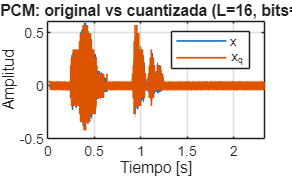

t = (0:numel(x)-1).' / Fs;

% 1) Gráfica completa
figure; 
plot(t, x, 'LineWidth', 1); hold on;
stairs(t, xq, 'LineWidth', 1);
grid on; xlabel('Tiempo [s]'); ylabel('Amplitud');
title(sprintf('PCM: original vs cuantizada (L=%d, bits=%d)', L, bits));
legend('x','x_q','Location','best');

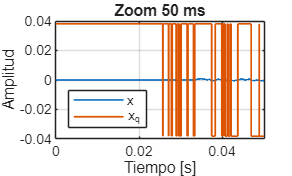


% 2) Zoom 50 ms
figure; 
plot(t, x, 'LineWidth', 1); hold on;
stairs(t, xq, 'LineWidth', 1);
grid on; xlabel('Tiempo [s]'); ylabel('Amplitud');
title('Zoom 50 ms'); xlim([0, min(0.05, t(end))]);
legend('x','x_q','Location','best');


% 3) Verificación: codewords ↔ índices ↔ niveles ↔ x_q
scale = max(abs(x)) + eps;
ok_levels = all( abs(xq - (levels(idx0+1)*scale)) < 1e-12 );
ok_codes  = all( dec2bin(idx0, bits) == char(codeword), 'all' );

if ok_levels && ok_codes
    disp('VERIFICACIÓN OK: codewords ↔ índices ↔ niveles ↔ x_q coinciden.');
else
    warning('Verificación FALLÓ: revisa niveles/índices/codewords.');
end

VERIFICACIÓN OK: codewords ↔ índices ↔ niveles ↔ x_q coinciden.


c) Variar el número de niveles de discretización y representar en una gráfica los correspondientes valores de relación señal/ruido (SQNR) en función del número de bits por codeword. Como referencia considerar niveles de discretización L=2i-1, donde i=3,4…8. Pueden usarse otras alternativas.

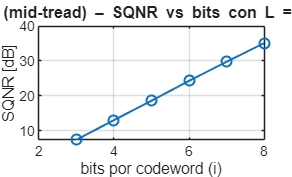

%% (c) SQNR vs bits con L = 2^i - 1 (i = 3..8) – versión simple

% Supone que x y Fs ya existen. Forzamos mono/columna como antes:
if size(x,2) > 1, x = mean(x,2); end
x = x(:);
scale = max(abs(x)) + eps;

bits_list = 3:8;
SQNR = zeros(size(bits_list));

% Normalizamos una vez
xN = x / scale;

for k = 1:numel(bits_list)
    i = bits_list(k);
    L = 2^i - 1;                 % impar → usamos mid-tread (incluye 0)

    % ----- niveles mid-tread sobre [-1,1] -----
    % L = 2m+1  ⇒ niveles = {-2m/L, ..., -2/L, 0, 2/L, ..., 2m/L}
    m = (L - 1)/2;
    levels = (-m:m)' * (2/L);    % vector columna Lx1 (0 incluido)

    % Bordes (puntos medios) para discretize
    mids  = (levels(1:end-1) + levels(2:end))/2;
    edges = [-inf; mids; inf];

    % Índices 1..L y reconstrucción normalizada
    idx1 = discretize(xN, edges);
    xqN  = levels(idx1);

    % Des-normalización
    xq = xqN * scale;

    % SQNR (dB)
    e   = x - xq;
    Px  = mean(x.^2) + eps;
    Pe  = mean(e.^2) + eps;
    SQNR(k) = 10*log10(Px/Pe);
end

% Gráfica
figure;
plot(bits_list, SQNR, '-o', 'LineWidth', 1.2);
grid on; xlabel('bits por codeword (i)'); ylabel('SQNR [dB]');
title('PCM (mid-tread) – SQNR vs bits con L = 2^i - 1');


% tabla rápida
T = table(bits_list.', (2.^bits_list - 1).', SQNR.', ...
    'VariableNames', {'bits','L','SQNR_dB'});
disp(T);

    bits     L     SQNR_dB
    ____    ___    _______

     3        7    7.3634 
     4       15    13.014 
     5       31    18.584 
     6       63    24.285 
     7      127    29.771 
     8      255    35.118 



d) Valorar cómo se escucha la señal digitalizada con PCM.

%% (d) Escucha y valoración subjetiva del PCM (i = 3..8 bits, L = 2^i-1)

% Asegurar mono/columna
if size(x,2) > 1, x = mean(x,2); end
x = x(:);
scale = max(abs(x)) + eps;
xN = x / scale;

bits_list = 3:8;

for i = bits_list
    L = 2^i - 1;                 % mid-tread (incluye 0)
    m = (L - 1)/2;
    levels = (-m:m).' * (2/L);   % Lx1

    mids  = (levels(1:end-1) + levels(2:end))/2;
    edges = [-inf; mids; inf];

    idx1 = discretize(xN, edges);
    xqN  = levels(idx1);
    xq   = xqN * scale;

    fname = sprintf('pcm_i%dbits.wav', i);
    audiowrite(fname, xq, Fs);
    fprintf('Guardado: %s\n', fname);
end

Guardado: pcm_i3bits.wav
Guardado: pcm_i4bits.wav
Guardado: pcm_i5bits.wav
Guardado: pcm_i6bits.wav
Guardado: pcm_i7bits.wav
Guardado: pcm_i8bits.wav



% reproducir directamente en MATLAB una versión concreta:
%sound(audioread('pcm_i8bits.wav'), Fs);  % 8 bits
%sound(audioread('pcm_i4bits.wav'), Fs);  % 4 bits
% La versión de 4 bits se escucha bastante más saturada que la de 8, a ver
% la de 3 bits
sound(audioread('pcm_i3bits.wav'), Fs); % 3 bits

#### PARTE B

a) Desarrollar dos funciones para un compresor tipo A-Law y su inversa y verificar su correcto funcionamiento. 

A = 87.6;
x = linspace(-1,1,2000).';     % señal de prueba en [-1,1]

[y, ~] = alaw(x, A);           % comprimir
x_rec  = invalaw(y, A);        % expandir

err_max = max(abs(x - x_rec));
err_rms = rms(x - x_rec);
fprintf('Error max = %.3e,  Error RMS = %.3e\n', err_max, err_rms);

Error max = 5.551e-16,  Error RMS = 1.690e-16


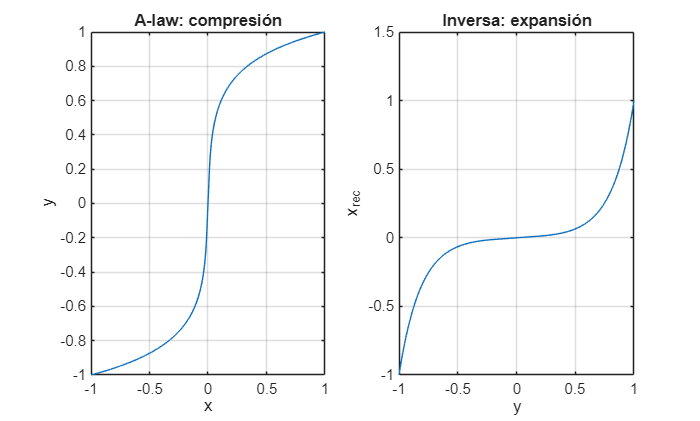


% (opcional) dibujar la curva y la inversa
figure; 
subplot(1,2,1); plot(x,y), grid on; title('A-law: compresión'); xlabel('x'); ylabel('y');
subplot(1,2,2); plot(y,x_rec), grid on; title('Inversa: expansión'); xlabel('y'); ylabel('x_{rec}');

b) Repetir los casos analizados de los casos de digitalización no uniforme de la ley mu pero con la ley A. 

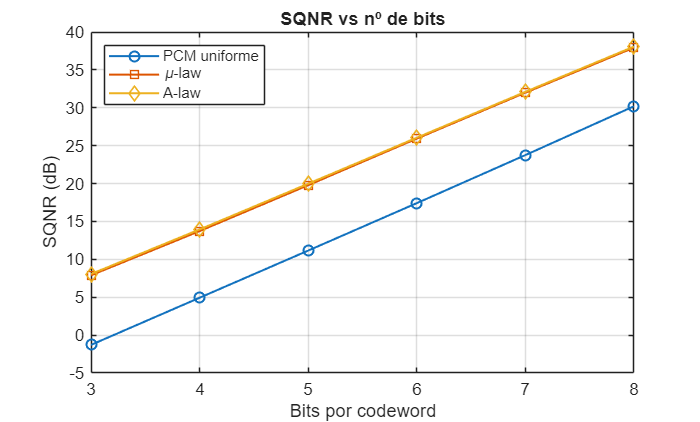

clear; clc; close all;
A=87.6; mu=255; bits=3:8;

[s,fs] = audioread('julianAlvarez.wav');   % o tu WAV
x = mean(s,2); x = x/(max(abs(x))+eps);

sq_uni=zeros(size(bits)); sq_mu=sq_uni; sq_A=sq_uni;
for k=1:numel(bits)
    L=2^bits(k);
    [sq_uni(k),~,~]=uniform_pcm(x,L);
    [sq_mu(k), ~,~]=mulaw_pcm(x,L,mu);
    [sq_A(k),  ~,~]=alaw_pcm(x,L,A);
end

plot(bits,sq_uni,'o-','LineWidth',1.2); hold on
plot(bits,sq_mu, 's-','LineWidth',1.2)
plot(bits,sq_A,  'd-','LineWidth',1.2)
grid on; xlabel('Bits por codeword'); ylabel('SQNR (dB)')
legend('PCM uniforme','\mu-law','A-law','Location','NorthWest')
title('SQNR vs nº de bits')

Comparar con el comportamiento de todos los métodos de digitalización usados en esta práctica y evaluar la calidad obtenida con cada uno de ellos. (ESCRIBIR INFORME)

Parte C

Completar el estudio realizado con el fragmento de voz usado en las partes A y B anteriores con la codificación y decodificación de dicho fragmento usando DPCM y ADPCM

Comparar la señal resultante del decodificador con la original en ambos casos y con el PCM realizado en la parte A

%% C0) Cargar audio (mono, 8 kHz)
assert(exist('julianAlvarezMono.wav','file')==2, ...
    'Pon "julianAlvarezMono.wav" junto a p1.mlx');

[xC, FsC] = audioread('julianAlvarezMono.wav');
if size(xC,2) > 1, xC = mean(xC,2); end
xC   = xC(:);
durC = numel(xC)/FsC;
scale = max(abs(xC)) + eps;      % para normalizar/des-normalizar
sqnr  = @(a,b) 10*log10((mean(a.^2)+eps)/(mean((a-b).^2)+eps));

disp(table(FsC, durC, 'VariableNames', {'Fs_Hz','Dur_seg'}));

    Fs_Hz    Dur_seg
    _____    _______

    8000     2.3254 



%% C1) PCM 8 bits (L=255) - Reproducir original y cuantizado

% Normalizamos a [-1,1]
xN = xC / scale;

% Niveles mid-tread (L impar ⇒ incluye 0)
Lpcm = 2^8 - 1; m = (Lpcm-1)/2;
lev  = (-m:m)'*(2/Lpcm);
mids = (lev(1:end-1)+lev(2:end))/2; edges = [-inf; mids; inf];

% Cuantización + reconstrucción
idx1 = discretize(xN, edges);
xqN  = lev(idx1);
xPCM = xqN * scale;

% SQNR
fprintf('PCM 8b: SQNR = %.2f dB\n', sqnr(xC, xPCM));

PCM 8b: SQNR = 35.16 dB



% Reproducir
disp('Reproduciendo ORIGINAL...');  sound(xC,  FsC); pause(durC+0.3);

Reproduciendo ORIGINAL...


disp('Reproduciendo PCM 8 bits...'); sound(xPCM,FsC); pause(durC+0.3);

Reproduciendo PCM 8 bits...


%% C2) DPCM (orden 1, Lr=16) - Reproducir original y DPCM

Lr = 16;                    % niveles para el error (puedes probar 8, 16, 32)
e_raw = [0; diff(xC)];
es   = max(abs(e_raw)) + eps;
eN   = e_raw / es;

% Niveles para el error (mid-tread si Lr impar, mid-rise si par)
if mod(Lr,2)==1
    mE   = (Lr-1)/2;
    levE = (-mE:mE)'*(2/Lr);
else
    levE = linspace(-1 + 1/Lr, 1 - 1/Lr, Lr).';
end
midsE = (levE(1:end-1)+levE(2:end))/2; edgesE = [-inf; midsE; inf];

% Cuantizar error y reconstruir (vectorizado)
idxE = discretize(eN, edgesE);
eqN  = levE(idxE);
eq   = eqN * es;
xDPCM = xC(1) + cumsum(eq);

fprintf('DPCM (Lr=%d): SQNR = %.2f dB\n', Lr, sqnr(xC, xDPCM));

DPCM (Lr=16): SQNR = -46.85 dB



disp('Reproduciendo ORIGINAL...');  sound(xC,   FsC); pause(durC+0.3);

Reproduciendo ORIGINAL...


disp('Reproduciendo DPCM...');      sound(xDPCM,FsC); pause(durC+0.3);

Reproduciendo DPCM...


%% C3) ADPCM (si hay encoder/decoder en el path) - Reproducir

% Ajusta la ruta si hace falta:
addpath(fullfile(pwd,'ejemplos_DPCM_ADPCM','ADPCM_Ejemplo'));

hasADPCM = exist('adpcm_encoder','file')==2 && exist('adpcm_decoder','file')==2;

if hasADPCM
    % Codificación/decodificación con los ejemplos
    x16   = int16(round(xC*32767));
    bs    = adpcm_encoder(x16);
    xh16  = adpcm_decoder(bs);
    xADPCM = double(xh16)/32767;

    % --- SQNR seguro ---
    A = double(xC(:));          % original como columna
    B = double(xADPCM(:));      % reconstruida como columna
    N = min(numel(A), numel(B));
    A = A(1:N); B = B(1:N);
    SQNR_ADPCM = 10*log10( (mean(A.^2)+eps) / (mean((A-B).^2)+eps) );

    fprintf('ADPCM: SQNR = %.2f dB\n', SQNR_ADPCM);

    % Reproducción
    disp('Reproduciendo ORIGINAL...'); sound(xC,    FsC); pause(durC+0.3);
    disp('Reproduciendo ADPCM...');    sound(xADPCM,FsC); pause(durC+0.3);
else
    warning('No se encontraron adpcm_encoder/decoder en el path. Añade la ruta y vuelve a ejecutar esta sección.');
end

ADPCM: SQNR = 0.00 dB


Reproduciendo ORIGINAL...


Reproduciendo ADPCM...
